clc;
close all;
clear all;


disp('--- start ---')

--- start ---


## Part 1: Data Loading and Spliting

df = readtable('epilepsyfinal.csv');                 % Import data as a csv into a master dataset

% Spliting the dataset into Training dataset and Testing dataset

p = 0.2;                                             % Holdout rate = 20%  meaning: 20% of the data from the master dataset will be held out for Testing purpose, the other 80% of data will be used from model training

cv = cvpartition(size(df,1),"Holdout",p);            % split the dataset into 80%-20% and shuffle the data
ind = cv.test;

dtrain = df(~ind,:);                                 % Indexing the training dataset as dtrain

dtest = df(ind,:);                                   % Indexing the testing dataset as dtest

trafeature = dtrain(:,2:179);                        % training features
tesfeature = dtest(:,2:179);                         % testing features

tratarget = dtrain(:,180);                           % training target
testarget = dtest(:,180);                            % testing target



## Part 2: Prevalence Check for each dataset to prevent bias

disp('the prevalence for the master dataset is: ')

the prevalence for the master dataset is: 


tabulate(df{:,180});                                  % Check the prevalence for master dataset

  Value    Count   Percent
      0     9200     80.00%
      1     2300     20.00%



disp('the prevalence for the training dataset is: ')

the prevalence for the training dataset is: 


tabulate(tratarget{:,:});                             % Check the prevalence for training dataset

  Value    Count   Percent
      0     7372     80.13%
      1     1828     19.87%



disp('the prevalence for the testing set is: ')

the prevalence for the testing set is: 


tabulate(testarget{:,:});                             % Check the prevalence for the testing dataset

  Value    Count   Percent
      0     1828     79.48%
      1      472     20.52%


## Part 3: Finding Hyper-Parameters for Naive Bayes Model using Grid-Search

w = 0.05;                                             % set each grid's width, it is the unit of each prior trial
mwd = 1/w;                                            % Maximum number of possible prior combination theorecticall
dist = {'kernel','mvmn','normal'};                    % Build up a distribution list. Leave out the 'mv' as it only for categorical non-negative features
hypar = [];                                           % Create an empty list to should the parameter combination with its according error rate

for a = 1:(mwd-1)                                     % the maximum number of prior trial. The reason to minus 1 is to make sure there are two priors for all hyper-parameters
    for b = 1:size(dist,2)                            % try each distribution in the distribution list
        tp = [a*w,1-a*w];                             % run through each priors combination

        Mdl1 = fitcnb(trafeature,tratarget, ...       % apply each parameter into the Naive Bayes classifier function
            'DistributionNames',cell2mat(dist(:,b)), ...
            'Prior',tp);
        
        cvmdl1 = crossval(Mdl1,'Holdout',0.2);        % Cross-Validation with Training data being split into 80-20
        L = kfoldLoss(cvmdl1);                        % Calculate the k-fold loss error (we use 10 folds, as default)

        hypar = [hypar;tp,dist(:,b),L];               % As the for-loop runs, it will produce a matrix (57x3). Each row of the matrix consists of: the prior pair, distribution and according loss rate
        

    end
end

disp(hypar);

## Part 4: Finding the HyperParameter for Training dataset with NB model

% After running the grid search, we spot out the combination of parameters
% with least loss error is:

% Prior pair = [0.85,0.15];
% Distribution = 'kernel';
% Loss error = 0.0395;



## Part 5: Use HyperParameters in NB model in Training Naive Bayes Classifiers

% Apply the HyperParameter (Prior and Distribution) to the NB model

hypirior = [0.85,0.15];                                % Hyper-Parameter's Prior pair
hydist = 'kernel';                                     % Hyper-Parameter's distribution

Mdltra = fitcnb(trafeature, tratarget, ...             % Applying hyper-parameters to NB model and build the optimal NB model
    'Prior', hypirior, ...
    'DistributionName', hydist);
save('Mdltra.mat','Mdltra');                           % Save the optimal model for summoning later

% Check the Performance on the Training dataset

label = predict(Mdltra,trafeature);
perf = sum(label==tratarget{:,:})/size(label,1);
a = loss(Mdltra,trafeature,tratarget);

% Display the performance of NB using HyperParameter in Training dataset
disp('The performance of NB model using HyperParameter in Training datset is: ')

The performance of NB model using HyperParameter in Training datset is: 


disp(perf);

    0.9598



disp('The rate of error on Training dataset is: ')

The rate of error on Training dataset is: 


disp(a);

    0.0370



## Part 6: Applying Optimal NB model in Testing Dataset

Mdltes = fitcnb(trafeature, tratarget, ...              % Applying optimal NB model with hyper-parameters for Testing dataset
    'Prior', hypirior, ...
    'DistributionName', hydist);
save('Mdltes.mat','Mdltes');                            % Save the result of optimal NB model with the testing dataset for later summon

## Part 7: Test performance of the Optimal NB Model on Testing dataset

load('Mdltes.mat');                                     % Summoning the optimal NB model result of test dataset
testresult = predict(Mdltes,tesfeature);                % Use the result of the optimal NB model to predict classes for the test dataset targets using testing feature

label2 = predict(Mdltes,tesfeature);                    % Check the Performance on the Testing dataset
perf2 = sum(label2==testarget{:,:})/size(label2,1);     % Calculate the performance
a2 = loss(Mdltes,tesfeature,testarget);                 % Get the loss error rate on prediction with the testing dataset


## Part 8: Output Display

### 1. Confustion metrix

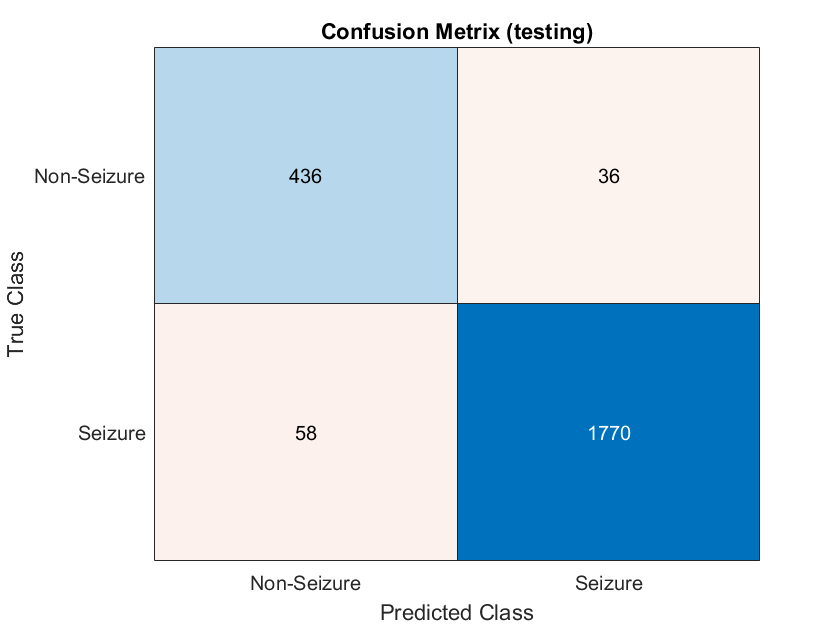

cm = confusionmat(testarget{:,:},testresult,'Order',[0,1]);              % Create the confusion matrix based on the testing dataset's observation and prediction
classlabel = ["Seizure","Non-Seizure"];                                  % Label the X and Y of confusion matrix
c = confusionchart(cm,classlabel,"Title","Confusion Metrix (testing)");  % Draw the confusiom matrix and name it

### 2. AUC-ROC curve

[X,Y,T,AUC] = perfcurve(testarget{:,:},testresult,1);                    % Create the AUC-ROC curve for testing the model's prediction accuracy
AUC

AUC = 0.9460

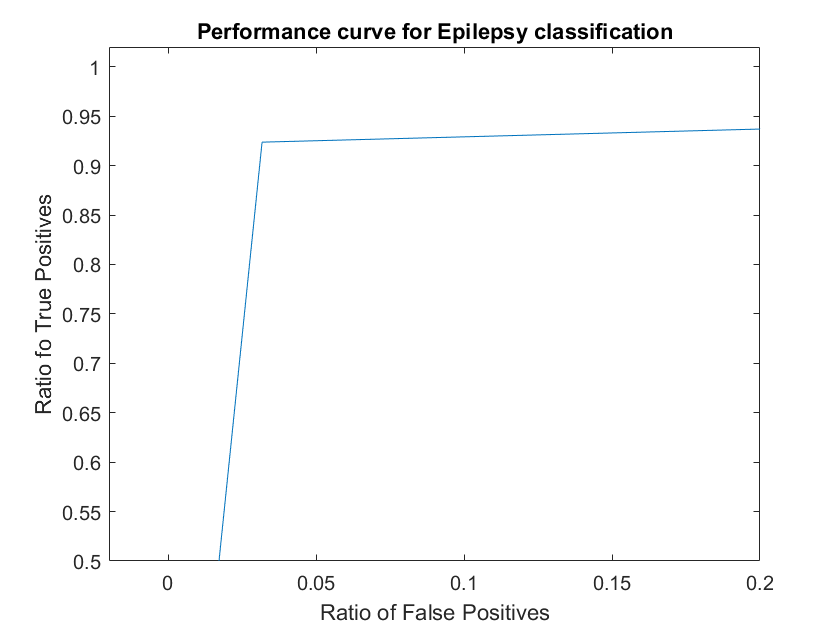


figure
plot(X,Y);                                                               % Plot the AUC-ROC curve with true positive rate and false positive rate

set(gca,'XLim',[-0.02,0.2],'YLim',[0.5,1.02]);                           % adjust the X-axis and Y-axis to make the graph easier to read
xlabel('Ratio of False Positives');                                      % Set the X label
ylabel('Ratio fo True Positives');                                       % Set the Y label
title('Performance curve for Epilepsy classification');                  % Set the title of the AUC-ROC curve

### 3. Accuracy and Error display

% We are about to calculate the precision rate, Recall Rate, Accuracy Rate
% and F1-score for from the confusion matrix we built above. The purpose is
% to see how accurate this optimal NB model could predict epileptic
% seizure.

% Precision Rate: (True Positive)/(Total Predicted Positive)
% It describe the the accuracy that out of the people predicted as
% "epileptic" are actually epileptic dignosed.

% Recall Rate: (True Positive)/(Total Actual Positive)
% It describes the rate that patient classified as ‘epileptic’ are actually epileptic. 

% F1-score: 2 * (precision rate * recall rate)/(precision rate + recall rate).
% It is a balanced score for precision and recall rate. 


trpo = Y(2,1);                                                           % True Positive Rate
fapo = X(2,1);                                                           % False Positive Rate
trne = (1-fapo);                                                         % True Negative Rate
fane = (1-trpo);                                                         % False Negative Rate
precision = trpo/(trpo + fapo);                                          % Compute the Precision Rate
recall = trpo/(trpo + fane);                                             % Compute the Recall value
accuracy = (trpo + trne)/(trpo + trne +fapo +fane);                      % Compute the Accuracey Rate
f1score = 2 * (precision * recall)/(precision + recall);                 % Compute the F1-score


disp('The performance of NB model using HyperParameter in Training datset is: ')

The performance of NB model using HyperParameter in Training datset is: 


disp(perf);

    0.9598



disp('The rate of error on Training dataset is: ')

The rate of error on Training dataset is: 


disp(a);

    0.0370




disp('The Performance of NB model using HyperParameter in Testing datset is: ')

The Performance of NB model using HyperParameter in Testing datset is: 


disp(perf2);

    0.9591



disp('The rate of error on Testing dataset is: ')

The rate of error on Testing dataset is: 


disp(a2);

    0.0384




disp('The Accuracy Rate of Testing dataset is:');

The Accuracy Rate of Testing dataset is:


disp(accuracy);

    0.9460




disp('The precision of Testing dataset is:');

The precision of Testing dataset is:


disp(precision);

    0.9668




disp('the Recal score Testing dataset is:');

the Recal score Testing dataset is:


disp(recall);

    0.9237




disp('The f1-Score of the Testing dataset is:')

The f1-Score of the Testing dataset is:


disp(f1score);

    0.9448




disp('AUC value of the Testing dataset is:')

AUC value of the Testing dataset is:


disp(AUC)

    0.9460

